close all
clear
clc

定义系统

a = [1, 2, 3];
b = [1, 1];
sys = tf(b,a);

定义采样时刻和激励1

t = [0:0.1:10]';
e1 = t.^2;

仿真激励1的系统响应

r1 = lsim(sys,e1,t);

定义激励2和仿真激励2的响应

e2 = exp(t);
r2 = lsim(sys,e2,t);

绘图：左子图绘制激励1和响应，右子图激励2和响应

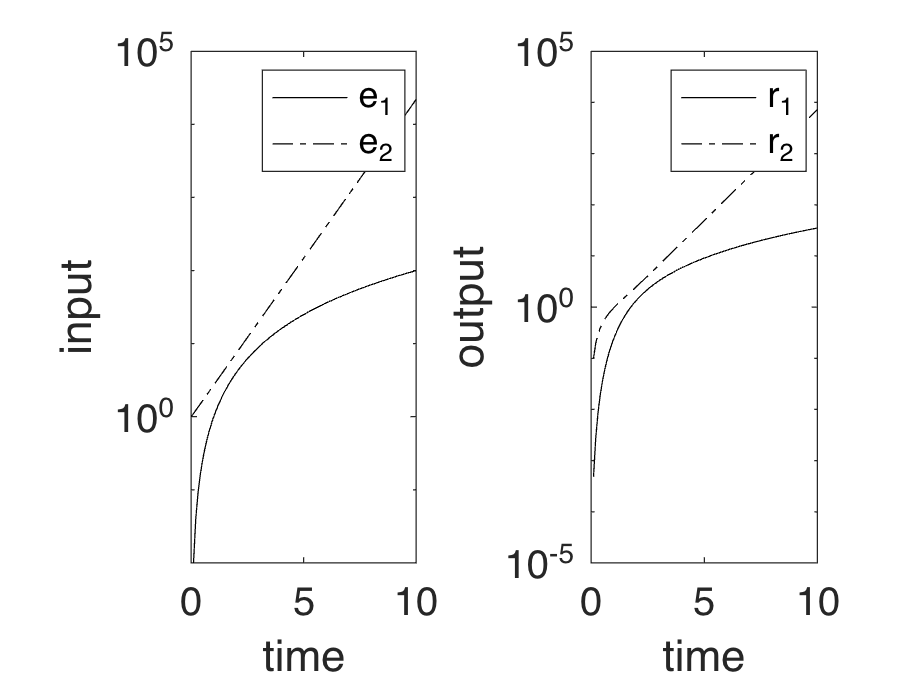

figure;
subplot(1,2,1), hold on, box on;
set(gca,'YScale','log');
set(gca,'FontSize',16);
plot(t,e1,'k-',t,e2,'k-.');
legend('e_1','e_2');
xlabel('time');
ylabel('input');

subplot(1,2,2), hold on, box on;
set(gca,'YScale','log');
set(gca,'FontSize',16);
plot(t,r1,'k-',t,r2,'k-.');
legend('r_1','r_2');
xlabel('time');
ylabel('output');